# **Matlab案例代码解析**

## 4. 图像信号处理案例

### 4.3 知乎提问

#### 4.3.2 MATLAB 求图像的部分区域平均灰度值？

原问题：[https://www.zhihu.com/question/526137288/answer/2424640899](https://www.zhihu.com/question/526137288/answer/2424640899)

# MATLAB 求图像的部分区域平均灰度值？MATLAB怎么求图像的部分区域平均灰度值？

比如MATLAB自带的米粒图像，获取每个米粒的平均灰度值

该怎么做，有代码更好

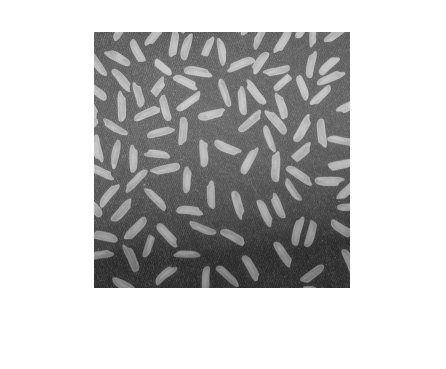

clear;clc;
img = imread('rice.png');
imshow(img);

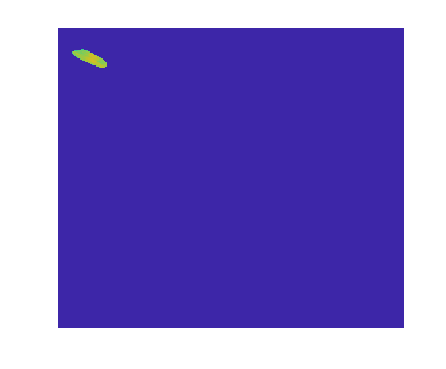

% 二值化
data = 255 * imbinarize(img, 'adaptive');
% 分割出每个部分

% 这里就指定一个区域
x = 28;
y = 28;
% 获取 ROI
J = RegionGrowing(data, [x, y], 20);
% 获取到原图区域
img_obj = double(img) .* J;
image(img_obj)
axis off

% 灰度均值
gray_ave = sum(img_obj(:)) / sum(img_obj(:) > 0)

gray_ave = 179.3125